clear all;
close all;
clc;
[xn,fs] = audioread('sample_audio_file.wav');
% convert from stero to mono 
xn = mean(xn,2);
N_xn = length(xn);
% axis of drawing 
t = linspace(0, N_xn/fs ,N_xn);
f = linspace(0, fs ,N_xn);

%Filter Specs
Fp = 3000;
Fs = 4000;
Ap = 1;
As = 50;
% Normalize Frequencies
Wp = Fp/(fs/2);
Ws = Fs/(fs/2);
% minimum order and cutoff_normalized_freq for each filter
[butter_order,Wc_butter] = buttord(Wp,Ws,Ap,As);
butter_order

butter_order = 22

Fc_butter=Wc_butter*(fs/2)

Fc_butter = 3.1078e+03

[cheb1_order,Wc_cheb1] = cheb1ord(Wp,Ws,Ap,As);
cheb1_order

cheb1_order = 9

Fc_cheb1=Wc_cheb1*(fs/2)

Fc_cheb1 = 3000

[cheb2_order,Wc_cheb2] = cheb2ord(Wp,Ws,Ap,As);
cheb2_order

cheb2_order = 9

Fc_cheb2=Wc_cheb2*(fs/2)

Fc_cheb2 = 4000

[ellip_order,Wc_ellip] = ellipord(Wp,Ws,Ap,As);
ellip_order

ellip_order = 6

Fc_ellip=Wc_ellip*(fs/2)

Fc_ellip = 3000

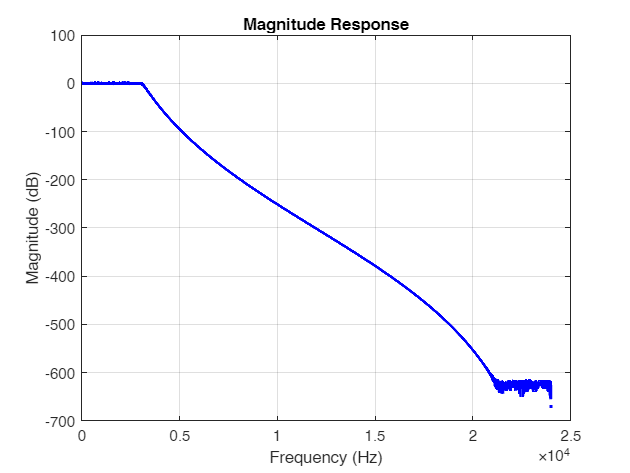


% apply x[n] for every filter
% 1) Butterworth
[b,a] = butter(butter_order,Wc_butter);
y_butter = filter(b,a,xn);
plotMagnitudeResponse(b,a,fs);

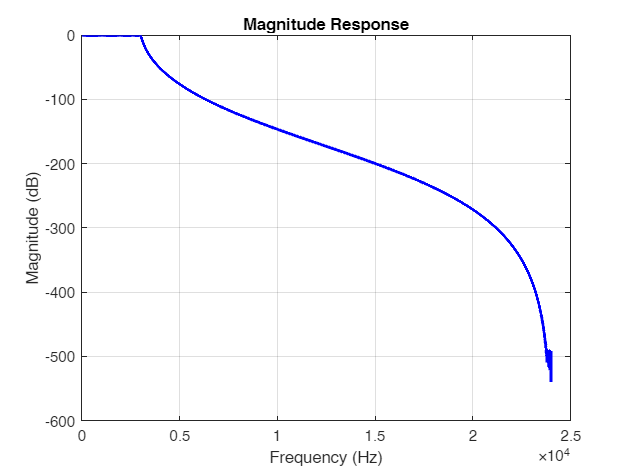

MSE_butter = (1/(N_xn+1)) * sum((y_butter(1:N_xn)-xn).^2);

% 2) Cheby 1
[b,a] = cheby1(cheb1_order,Ap,Wc_cheb1);
y_cheby1 = filter(b,a,xn);
plotMagnitudeResponse(b,a,fs);

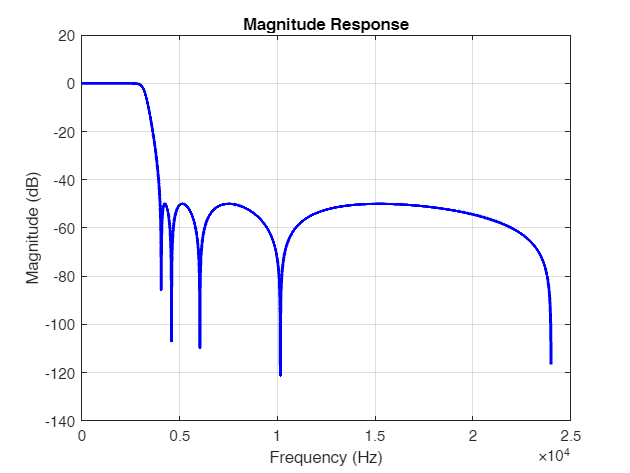

MSE_cheby1 = (1/(N_xn+1)) * sum((y_cheby1(1:N_xn)-xn).^2);

% 3) Cheby 2
[b,a] = cheby2(cheb2_order,As,Wc_cheb2);
y_cheby2 = filter(b,a,xn);
plotMagnitudeResponse(b,a,fs);

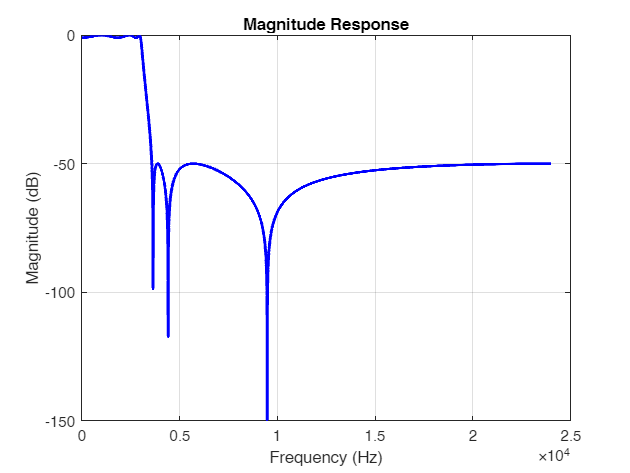

MSE_cheby2 = (1/(N_xn+1)) * sum((y_cheby2(1:N_xn)-xn).^2);

% 4) Elliptic
[b,a] = ellip(ellip_order,Ap,As,Wc_ellip);
y_ellip = filter(b,a,xn);
plotMagnitudeResponse(b,a,fs);

MSE_ellip = (1/(N_xn+1)) * sum((y_ellip(1:N_xn)-xn).^2);

MSE_butter

MSE_butter = 0.0018

MSE_cheby1

MSE_cheby1 = 0.0018

MSE_cheby2

MSE_cheby2 = 0.0010

MSE_ellip

MSE_ellip = 0.0011